**2. Filtering, linear systems, and Fourier analysis**

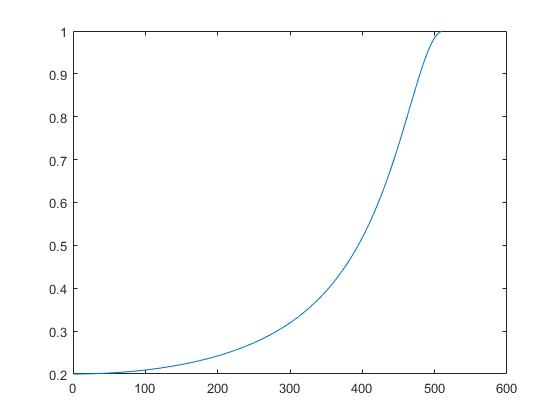

b = [1/3];
a = [1 2/3];

resp= abs(freqz(b,a,[]));
plot((0:length(resp)-1),resp)

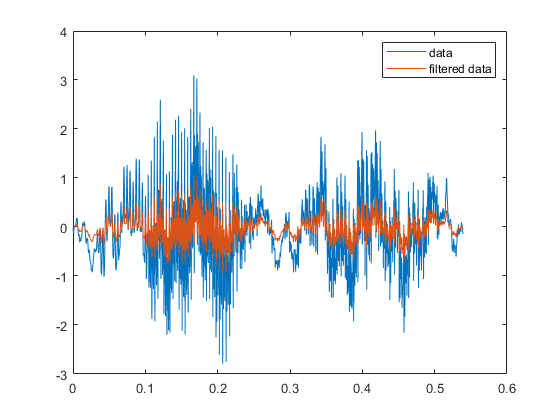

load("Exam\dataexam2020Question2.mat")

fs = 7418;
n = length(x);
t = (0:n-1)/fs;

xf = filter(b,1,x);

figure()
plot(t,x)
hold on
plot(t,xf)
hold off
legend('data','filtered data')

fx = abs(fft(x));
fxf = abs(fft(xf));

frange = (0:n-1)*(fs/n)

frange = 	1.0e+03 *

         0    0.0019    0.0037    0.0056    0.0074    0.0093    0.0111    0.0130    0.0148    0.0167    0.0185    0.0204    0.0222    0.0241    0.0260    0.0278    0.0297    0.0315    0.0334    0.0352    0.0371    0.0389    0.0408    0.0426    0.0445    0.0464    0.0482    0.0501    0.0519    0.0538    0.0556    0.0575    0.0593    0.0612    0.0630    0.0649    0.0667    0.0686    0.0705    0.0723    0.0742    0.0760    0.0779    0.0797    0.0816    0.0834    0.0853    0.0871    0.0890    0.0908


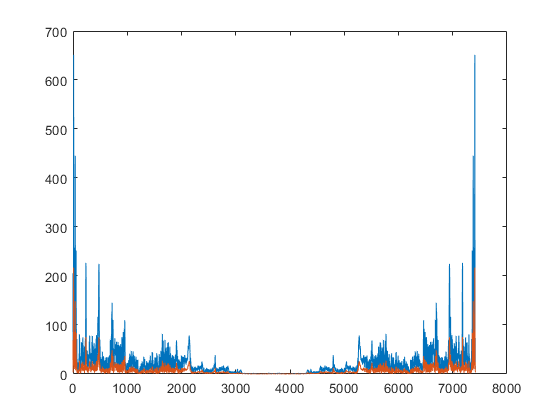


figure()
plot(frange,fx)
hold on
plot(frange,fxf)
hold off

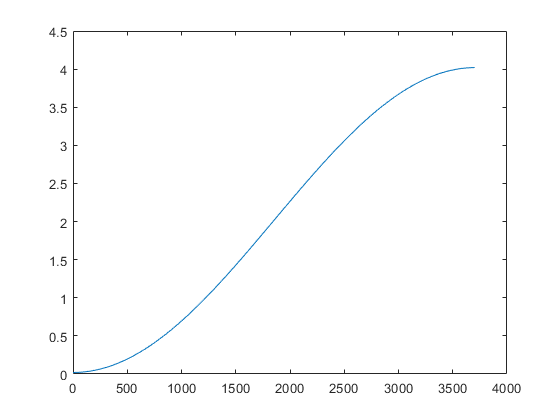

z1 = exp(i*2*pi*11.12/fs);
z2 = exp(-i*2*pi*11.12/fs);

syms z;
bsymb = expand((z-z1)*(z-z2)); 
b1 = sym2poly(bsymb);


resp1= abs(freqz(b1,1,[],fs));
frange1 = (0:length(resp1)-1)*(fs/(2*length(resp1)));

plot(frange1,resp1)

xf2 = filter(b,1,x);

figure()
plot(t,x)
hold on
plot(t,xf2)
hold off
legend('data','filtered data')